# some numbers.

## all times are in [ms]

dt  = 2;
tmax = 1998;
tmin = -1200;
fs = 1/dt;
len_sample = floor((tmax-tmin)*fs);
t = linspace(tmin, tmax, len_sample);

noise.tscales = [200, 200];
noise.amplitude = [0.5 1];
noise.jitters = [0 20:20:220] ;
noise.jitter = 0;
% noise.randn = 0.1;
noise.pink_alpha = -2.4;

jitters = noise.jitters;
num_trails = 300;
freqs = logspace(log10(2), log10(60), 30);

bl_range = find( -900 < t & t < -750);
u = t > -200 & t < 1000;

## generating erps data

erps = zeros(length(jitters), length(t));
trials = zeros(length(jitters), num_trails, length(t));
sub_trials = trials ;
for ii = 1:length(jitters)
    noise.jitter = noise.jitters(ii) * fs;
    trials(ii,:,:) = N200matWithNoise(t, num_trails, noise);
    erps(ii,:) = mean(trials(ii,:,:));
    sub_trials(ii,:,:) = bsxfun(@minus, squeeze(trials(ii,:,:)), erps(ii,:));
end

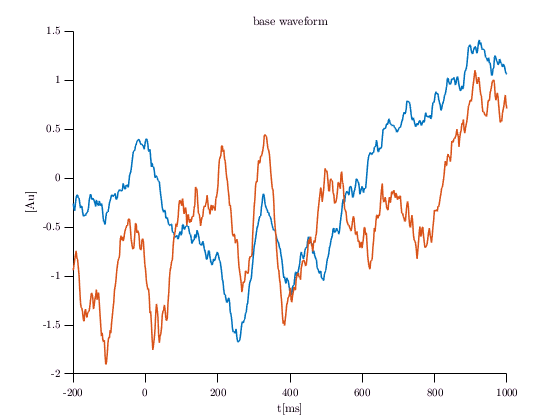


%% plot graph of each ERP with all trials
baseN2 = squeeze(trials(1:2,1,:))';
figure;
plot(t(u), baseN2(u,:) )
xlabel t[ms]
ylabel [Au]
title 'base waveform';

## plot graph of each ERP with its subtracted trials

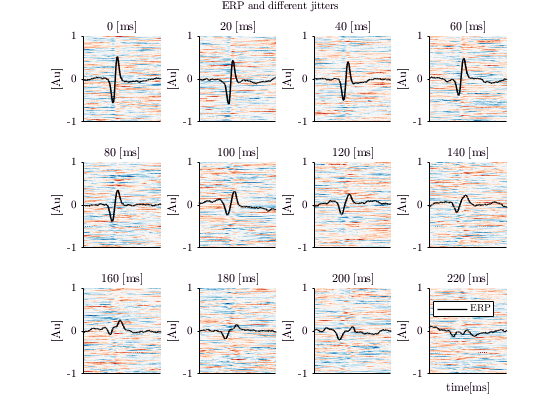

figure;
for ii = 1:length(jitters)
    % plotting all erps
    subplot(ceil(length(jitters)/4),4,ii);
    %     figure
    
    imagesc(t(u), [-1, 1], squeeze(trials(ii,:,u)));
    hold on
    plot(t, erps(ii,:), 'linewidth',1,'color','k');
%     plot(t, baseN2 , 'r--', 'linewidth',l1)
    
    axis xy
    caxis([min(sub_trials(:)), max(sub_trials(:))]);
    set(gca,'XTick',[]);
    ylabel [Au]
%     colormap jet
    title(sprintf('%d [ms]', jitters(ii)));
    hold off
end
legend({'ERP'})
xlabel time[ms]
add_subplot_title('ERP and different jitters')
set(gca,'xtickMode', 'auto')

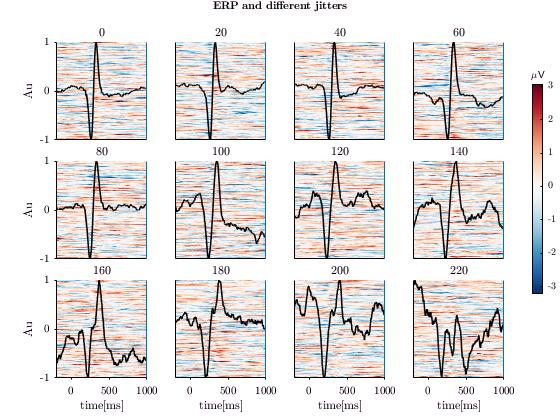

c_trials = mat2cell(trials(:,:,u), ones(1,length(jitters)), num_trails, sum(u));
figure;
show_trials_tight(t(u), c_trials, 4, 'ERP and different jitters', '\muV', erps(:,u)', jitters)

## spectral analysis

calculate spectrum

originals_freq_power = zeros([length(jitters) length(freqs) length(t)]);
subtrials_freq_power = originals_freq_power;
total_phase = zeros([size(originals_freq_power), num_trails]);

erps_freq_power = getPowerSpectra(erps,dt, freqs); %freq-time(-channel)
if(ndims(erps_freq_power))==2
    %for ploting competability
    erps_freq_power = reshape(erps_freq_power,[1 size(erps_freq_power)]);
else
    erps_freq_power = shiftdim(erps_freq_power,2); %channel-freq-time
end

parfor ii = 1:length(jitters)
    [amp,ph] = getPowerSpectra(squeeze(trials(ii,:,:)),dt,freqs);   
    bl_values = mean(mean(amp(:, bl_range, :),3),2);
    originals_freq_power(ii,:,:) = 10 * log10(bsxfun(@rdivide,mean(amp,3),bl_values));
    total_phase(ii,:,:,:) = ph;
    
    amp = getPowerSpectra(squeeze(sub_trials(ii,:,:)),dt,freqs);
%     bl_values = mean(mean(amp(:, bl_range, :),3),2);
    subtrials_freq_power(ii,:,:) = 10 * log10(bsxfun(@rdivide,mean(amp,3),bl_values));
    
    erps_freq_power(ii,:,:) = 10 * log10(bsxfun(@rdivide,squeeze(erps_freq_power(ii,:,:)),bl_values));
end

diff_original_subtracted_trials = originals_freq_power - subtrials_freq_power;


show table of phases for each jitter

figure;
show_powers_tight(t(u),freqs, shiftdim(circ_std(total_phase(:,:,u,:),[],[],4),1), 4, 'std of phases for different jitters', 'rad',[], jitters)

phase_hilbert = get_hilbert_phase(shiftdim(trials,2), 4.5, 8, dt*1000);

phase_stds = circ_std(phase_hilbert,[],[],3);
phase_mean = circ_mean(phase_hilbert,[],3);

figure;
h = plot(t(u & t<600),phase_stds(u & t<600,:));
legend(cellstr(num2str(jitters', 'jitter=%d ms')), 'Location', 'bestoutside')
set(h, {'color'}, num2cell(cool(length(h)),2));
xlabel 'Time [ms]'
ylabel 'std'
title({'std of the phase of Theta band for different jitters','Simulation with noise; n = 100'})
% set(gca, 'ColorOrder', [0.5 0.5 0.5; 1 0 0], 'NextPlot', 'replacechildren');

figure;
varplot(jitters,phase_stds(0 <t & t<500,:)','std');
% legend(cellstr(num2str(t(1:100:400)', 'times=%.3g [ms]')))
% set(h, {'color'}, num2cell(winter(length(h)),2));
xlabel 'jitter [ms]'
ylabel 'std'
title({'std of the phase of Theta band with 0<t<500 for different jitters','Simulation with noise; n = 100'})
grid on

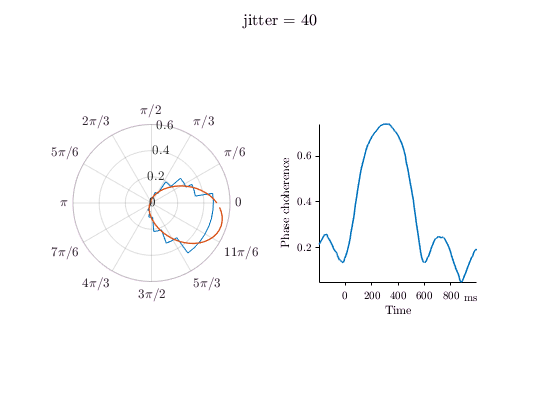

theta_phases_r = circ_r(phase_hilbert,[],[],3);
mask = u;
subj = 3;

[~,t_ind_subj] = max(theta_phases_r(:,subj));
subj_theta_phases = squeeze(phase_hilbert(t_ind_subj,subj,:));
% t_ind_subj = 100;
[thetahat, kappa] = circ_vmpar(subj_theta_phases);
[p,a]=circ_vmpdf([], thetahat, kappa);


figure
subplot(1,2,1)
polarhistogram(subj_theta_phases, 20,'Normalization','pdf',...
    'FaceAlpha',0, 'DisplayStyle','stairs');
pax = gca;
pax.ThetaAxisUnits = 'radians';
hold on
polarplot(a,p)

subplot(1,2,2)
%varplot(t,squeeze(mean(theta_phases_r(u,:,:),2)))
plot(t(u),theta_phases_r(u,subj))
axis tight
xlabel Time
axis square
ylabel 'Phase choherence'

xunits ms %replace
suptitle(sprintf('jitter = %d',jitters(subj)))


freq_mean = mean([4.5,8]);
jitter_estimate = sqrt(1-besseli(1,kappa)/besseli(0,kappa)) / freq_mean * 1e3;

fprintf('jitter estimate is %.0f [ms] at t ~ %.0f [ms]\n', jitter_estimate , t(t_ind_subj))

jitter estimate is 81 [ms] at t ~ 327 [ms]


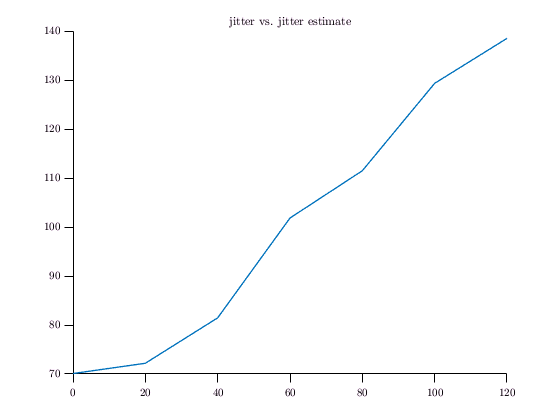


jitter_estimates = jitters*0;
kappas = jitters*0;
for subj = 1:length(jitters)

[~,t_ind_subj] = max(theta_phases_r(:,subj));
subj_theta_phases = squeeze(phase_hilbert(t_ind_subj,subj,:));
% t_ind_subj = 100;
[thetahat, kappa] = circ_vmpar(subj_theta_phases);

freq_mean = mean([4.5,8]);
% jitter_estimates(subj) = sqrt(1-besseli(1,kappa)/besseli(0,kappa)) / freq_mean * 1e3;
% jitter_estimates(subj) = (1-theta_phases_r(t_ind_subj,subj))/2/theta_phases_r(t_ind_subj,subj)^2;
jitter_estimates(subj) = circ_var(subj_theta_phases) * pi/2/freq_mean * 1e3;
kappas(subj) = kappa;
% jitter_estimates(subj) = 1/sqrt(kappa) / pi *2 / freq_mean * 1e3;

end
figure;
plot(jitters(jitters<130),jitter_estimates(jitters<130))
title 'jitter vs. jitter estimate'

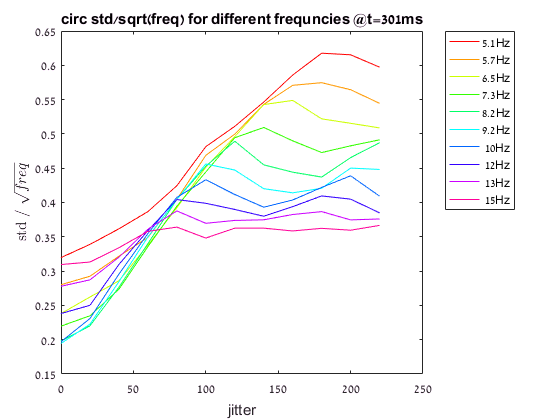

figure;
t_ind = find(t > 300,1);
freq_inds = freqs>5 & freqs<15;
h = plot(jitters, (circ_std(total_phase(:,freq_inds,t_ind,:),[],[],4))./sqrt(freqs(freq_inds)));
set(h, {'color'}, num2cell(hsv(length(h)),2));
legend(num2str(freqs(freq_inds)','%.2gHz'),'Location', 'bestoutside')
title(['circ std/sqrt(freq) for different frequncies @t=' int2str(t(t_ind)) 'ms'])
ylabel( 'std /  $\sqrt{freq}$', 'Interpreter','latex')
xlabel jitter

## power images for each jitter

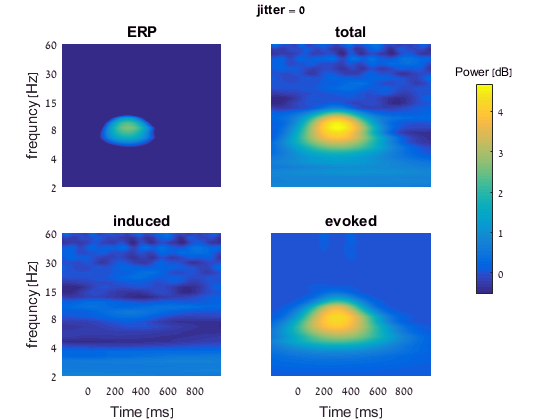

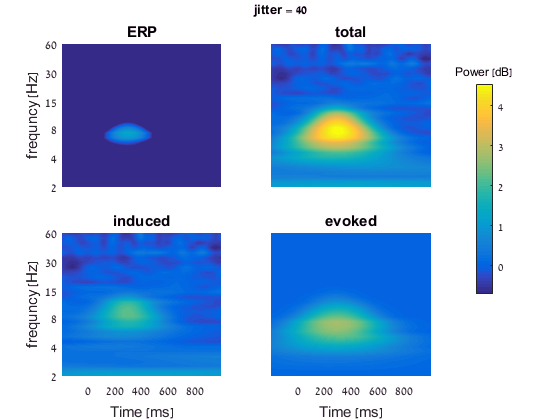

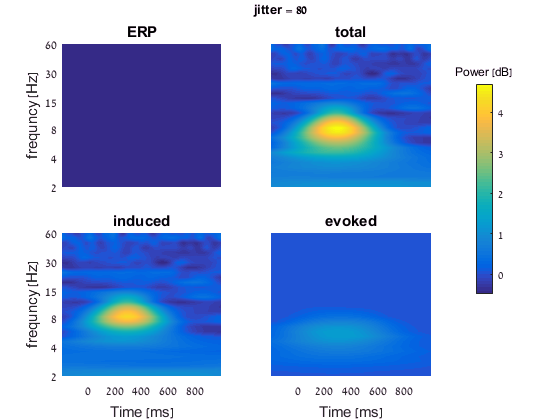

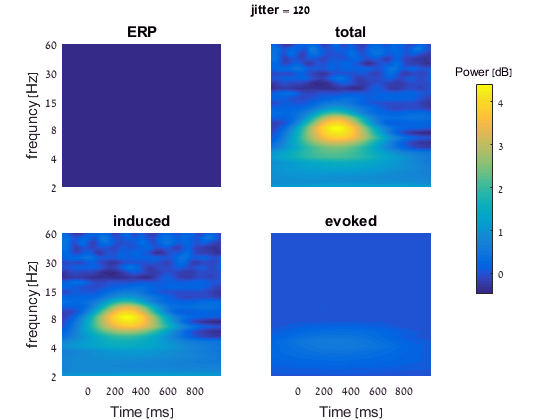

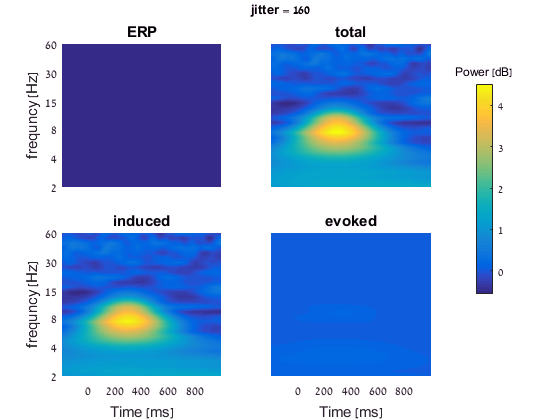

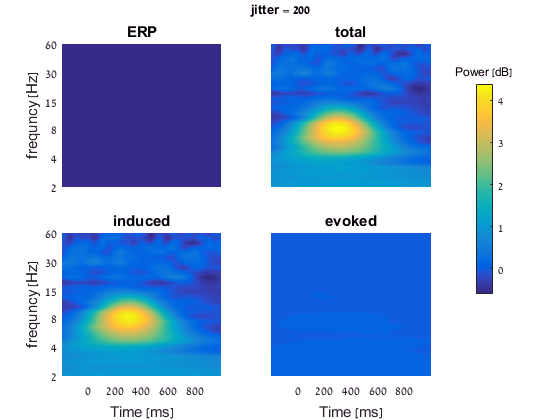



PlotType = 'surf';
for ii = 1:2:length(jitters)
    % ii=4;
    h = figure;
    show4images(t(u),freqs, ...
    squeeze(erps_freq_power(ii,:,u)), ...
    squeeze(originals_freq_power(ii,:,u)),  ...
    squeeze(subtrials_freq_power(ii,:,u)), ...
    squeeze(diff_original_subtracted_trials(ii,:,u)), ...
    ['jitter = ' num2str(jitters(ii))],...
    PlotType, true);
    
end

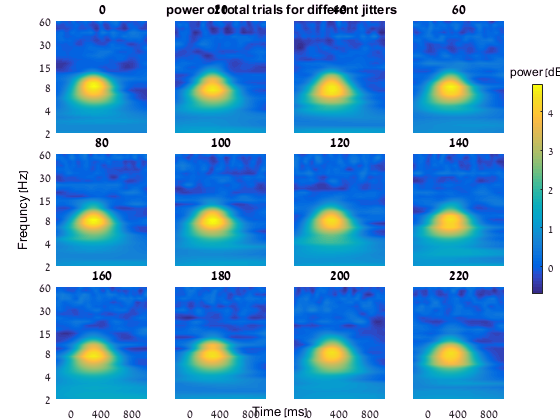

figure;
show_powers_tight(t(u), freqs, ...
shiftdim(originals_freq_power(:,:,u),1), ...
4, 'power of total trials for different jitters', ...
'power [dB]',[], jitters)

## Time Freq Plot

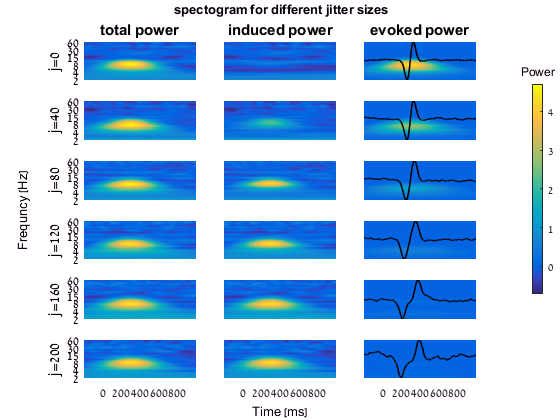

figure;
datas2show = zeros(size(originals_freq_power, 2), size(originals_freq_power, 3), size(originals_freq_power, 1)/2*3);
datas2show(:,:,1:3:end) = shiftdim(originals_freq_power(1:2:end,:,:),1);
datas2show(:,:,2:3:end) = shiftdim(subtrials_freq_power(1:2:end,:,:),1);
datas2show(:,:,3:3:end) = shiftdim(diff_original_subtracted_trials(1:2:end,:,:),1);
overlap_data = zeros(size(datas2show,2), size(datas2show,3));
overlap_data(:, 1:3:end) = nan;
overlap_data(:, 2:3:end) = nan;
overlap_data(:, 3:3:end) = erps(1:2:end,:)';

% title_freq = sprintf('subject=%d, resampled (%d X %d)', subj_ind, m, n);
show_powers_tight(t(u), freqs, datas2show(:,u,:), ...
3, 'spectogram for different jitter sizes', 'Power', overlap_data(u,:), ...
compose('j=%d', jitters(1:2:end)), ...
true, {'total power', 'induced power', 'evoked power'}, [] , 0.1, 0.15)

% colormap jet
%title_y, col_titles, gap,  marg_h, marg_w)


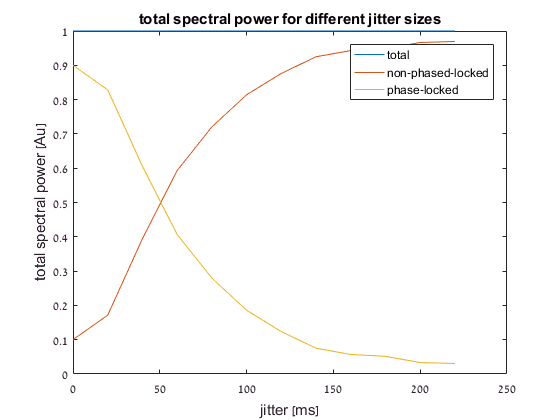

%% compare jitter size to sum of spectral information
figure
tot_freq_sum = @(X) sum(sum(X(:,:,u),2),3);
erps_freq_power_no_nan = erps_freq_power;
erps_freq_power_no_nan(erps_freq_power_no_nan < 0) = 0;
tot_erp = tot_freq_sum(erps_freq_power_no_nan);
tot_orig = tot_freq_sum(originals_freq_power);
tot_sub = tot_freq_sum(subtrials_freq_power);
tot_diff = tot_freq_sum(diff_original_subtracted_trials);

% plot(jitters, [tot_erp, tot_orig, tot_sub, tot_diff]');
plot(jitters, ([tot_orig, tot_sub, tot_diff]./tot_orig)');
legend({'total', 'non-phased-locked', 'phase-locked'})
% legend({'ERP', 'total', 'non-phased-locked', 'phase-locked'})
title 'total spectral power for different jitter sizes'
xlabel 'jitter [ms]'
ylabel 'total spectral power [Au]'

function add_subplot_title(title)
ha = axes('Position',[0 0 1 1],'Xlim',[0 1],'Ylim',[0 1],'Box','off','Visible','off','Units','normalized', 'clipping' , 'off');
text(0.5, 1,title,'HorizontalAlignment' ,'center','VerticalAlignment', 'top');
end


function show_time_freq(amp,time,freq, title_str)
        contourf(time,freq,amp);    
        grid on; colormap(parula(128)); 
    title(title_str)
    xlabel('time [ms]'); ylabel('freq [Hz]');
    set(gca,'yscale','log')
%     set(gca,'YLim',[0 4])
    set(gca,'YTick',round(logspace(log10(min(freq)), log10(max(freq)), 6))) 
end